v2 読んでみる

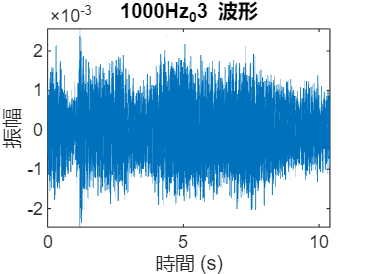

% WAV読み込み
[y, fs] = audioread('C:\Users\chika\COMOMO\1000hz_03.wav');
% y = 音声データ, fs = サンプルレート（4000Hzのはず）

% 波形表示
figure(1);
t = (0:length(y)-1) / fs;
plot(t, y);
xlabel('時間 (s)');
ylabel('振幅');
title('1000Hz_03 波形');

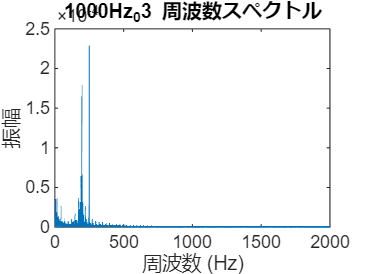


% フーリエ変換
figure(2);
N   = length(y);
Y   = fft(y);
f   = (0:N-1) * (fs/N);
amp = abs(Y(1:N/2)) / N;
plot(f(1:N/2), amp);
xlabel('周波数 (Hz)');
ylabel('振幅');
title('1000Hz_03 周波数スペクトル');
xlim([0 fs/2]);  % 0〜2000Hzの範囲

% WAV読み込み
[y, fs] = audioread('C:\Users\chika\COMOMO\1000hz_06.wav');  % ファイル名を実際のものに変更
y = y(:, 1);  % モノラル確認

% ============================================================
% 基本情報
% ============================================================
fprintf('=== 基本情報 ===\n');

=== 基本情報 ===


fprintf('サンプルレート : %d Hz\n', fs);

サンプルレート : 4000 Hz


fprintf('サンプル数     : %d\n', length(y));

サンプル数     : 40960


fprintf('録音時間       : %.2f 秒\n', length(y)/fs);

録音時間       : 10.24 秒


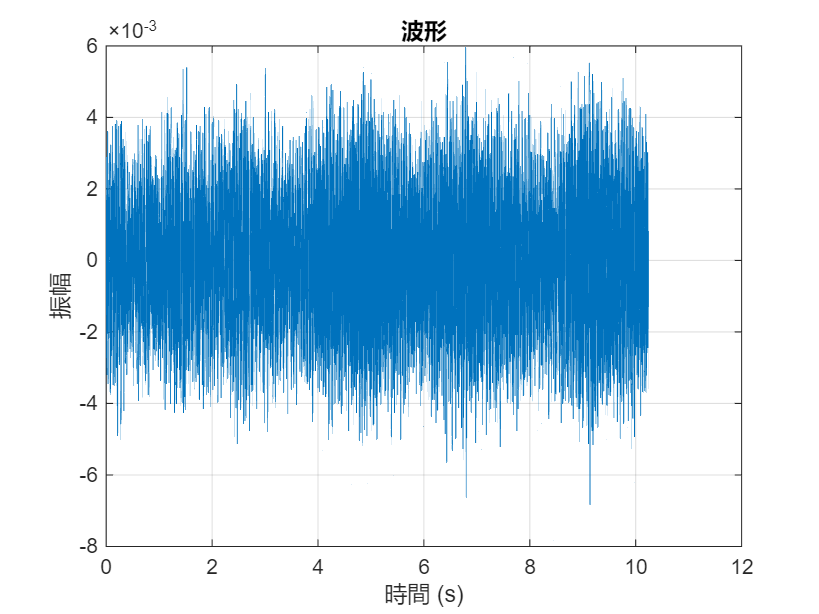


% ============================================================
% 波形表示
% ============================================================
figure(1);
t = (0:length(y)-1) / fs;
plot(t, y);
xlabel('時間 (s)');
ylabel('振幅');
title('波形');
grid on;

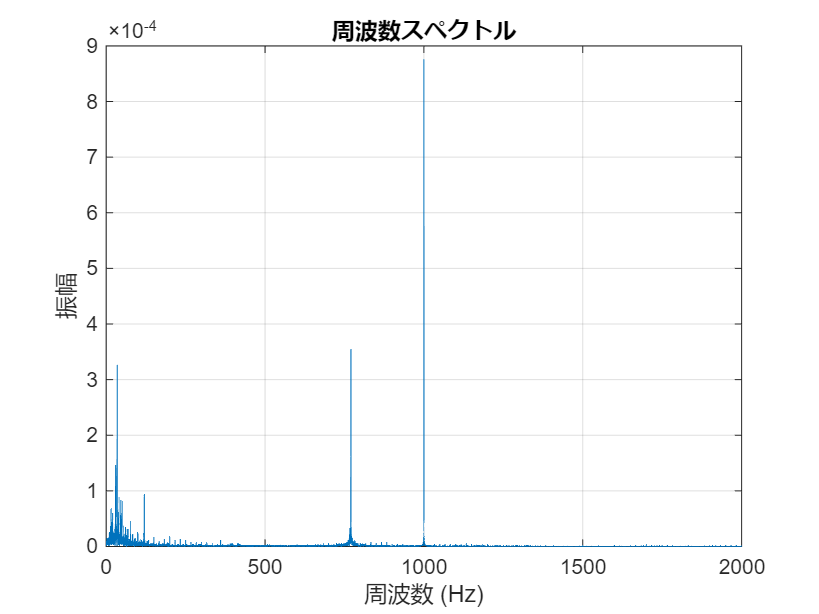


% ============================================================
% FFT（周波数解析）
% ============================================================
N   = length(y);
Y   = fft(y);
f   = (0:N-1) * (fs/N);
amp = abs(Y(1:floor(N/2))) / N;
f   = f(1:floor(N/2));

figure(2);
plot(f, amp);
xlabel('周波数 (Hz)');
ylabel('振幅');
title('周波数スペクトル');
grid on;
xlim([0 fs/2]);


% ============================================================
% Peak Frequency（上位5つ）
% ============================================================
fprintf('\n=== Peak Frequency ===\n');


=== Peak Frequency ===


[sortedAmp, sortedIdx] = sort(amp, 'descend');
fprintf('順位  周波数(Hz)  振幅\n');

順位  周波数(Hz)  振幅


fprintf('----  ----------  --------\n');

----  ----------  --------


for i = 1:5
    fprintf('%3d   %8.1f    %.6f\n', i, f(sortedIdx(i)), sortedAmp(i));
end

  1     1000.0    0.000876
  2      770.3    0.000355
  3       34.7    0.000327
  4       33.0    0.000192
  5      769.8    0.000172


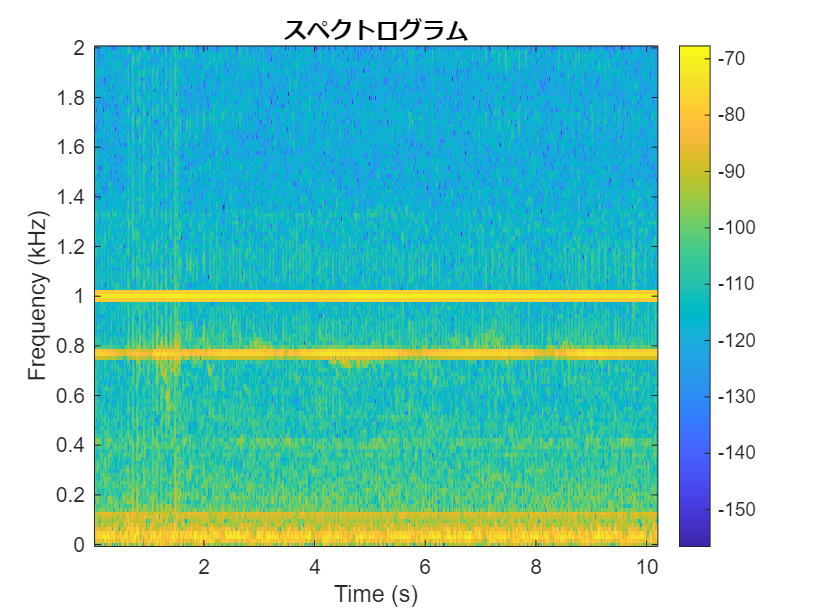


% ============================================================
% スペクトログラム（時間×周波数の2D表示）
% 音がどの時間帯にどの周波数が強いか見える
% ============================================================
figure(3);
spectrogram(y, 256, 200, 256, fs, 'yaxis');
title('スペクトログラム');
colorbar;

% WAV読み込み
[y, fs] = audioread('C:\Users\chika\COMOMO\500hz_06.wav');  % ファイル名を実際のものに変更
y = y(:, 1);  % モノラル確認

% ============================================================
% 基本情報
% ============================================================
fprintf('=== 基本情報 ===\n');

=== 基本情報 ===


fprintf('サンプルレート : %d Hz\n', fs);

サンプルレート : 4000 Hz


fprintf('サンプル数     : %d\n', length(y));

サンプル数     : 43360


fprintf('録音時間       : %.2f 秒\n', length(y)/fs);

録音時間       : 10.84 秒


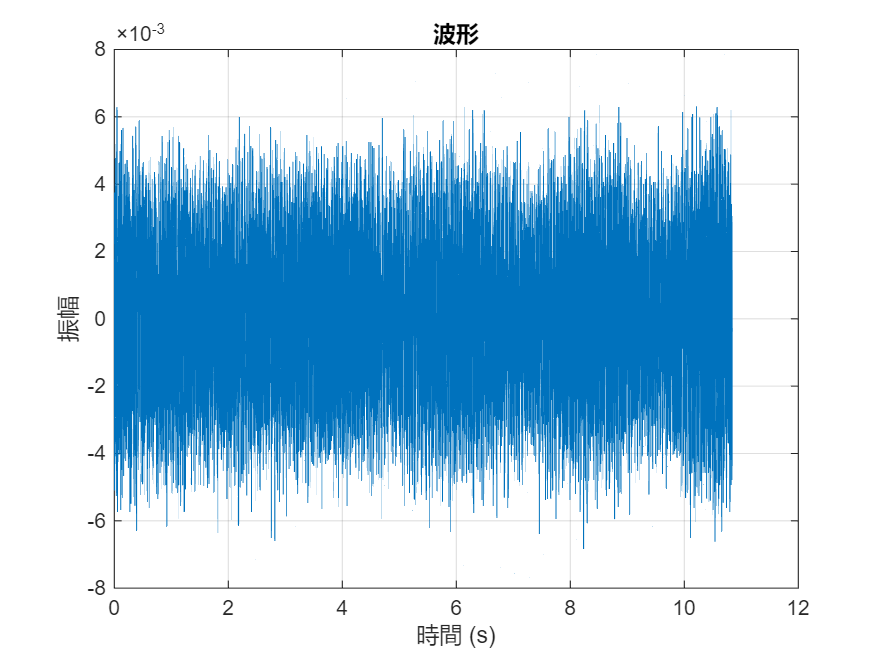


% ============================================================
% 波形表示
% ============================================================
figure(1);
t = (0:length(y)-1) / fs;
plot(t, y);
xlabel('時間 (s)');
ylabel('振幅');
title('波形');
grid on;

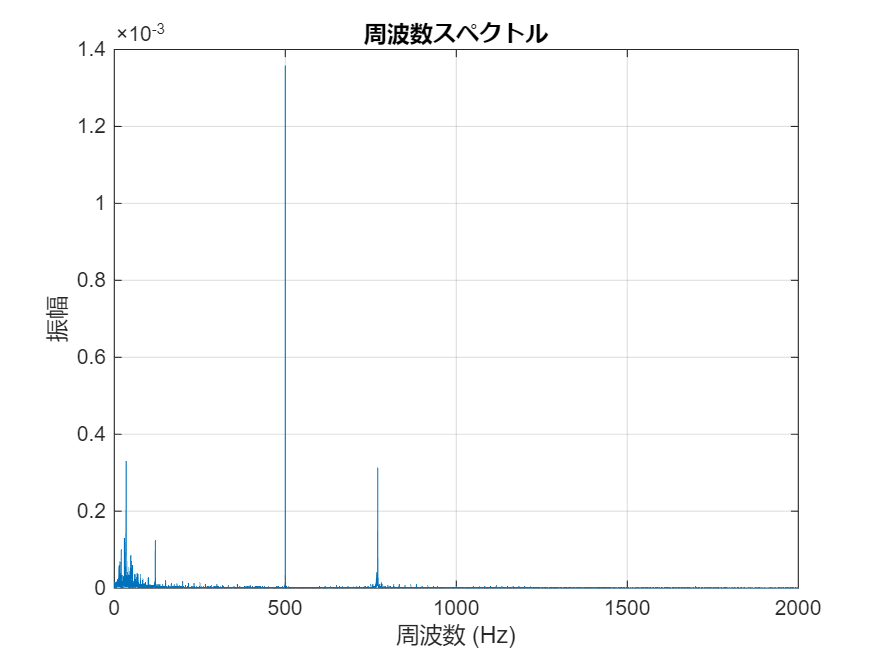


% ============================================================
% FFT（周波数解析）
% ============================================================
N   = length(y);
Y   = fft(y);
f   = (0:N-1) * (fs/N);
amp = abs(Y(1:floor(N/2))) / N;
f   = f(1:floor(N/2));

figure(2);
plot(f, amp);
xlabel('周波数 (Hz)');
ylabel('振幅');
title('周波数スペクトル');
grid on;
xlim([0 fs/2]);


% ============================================================
% Peak Frequency（上位5つ）
% ============================================================
fprintf('\n=== Peak Frequency ===\n');


=== Peak Frequency ===


[sortedAmp, sortedIdx] = sort(amp, 'descend');
fprintf('順位  周波数(Hz)  振幅\n');

順位  周波数(Hz)  振幅


fprintf('----  ----------  --------\n');

----  ----------  --------


for i = 1:5
    fprintf('%3d   %8.1f    %.6f\n', i, f(sortedIdx(i)), sortedAmp(i));
end

  1      500.0    0.001358
  2       34.7    0.000331
  3      770.3    0.000313
  4       33.0    0.000201
  5      769.8    0.000183


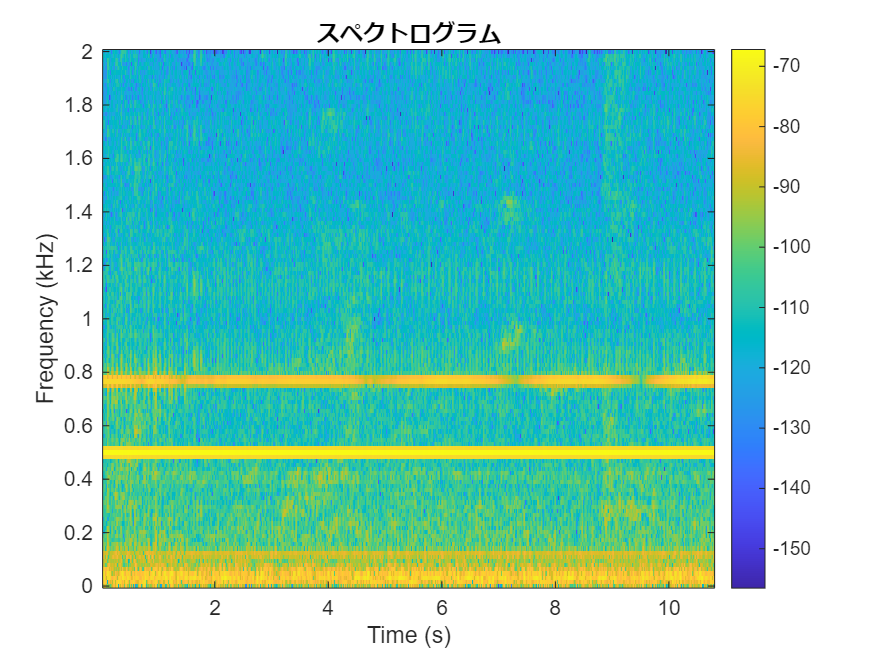


% ============================================================
% スペクトログラム（時間×周波数の2D表示）
% 音がどの時間帯にどの周波数が強いか見える
% ============================================================
figure(3);
spectrogram(y, 256, 200, 256, fs, 'yaxis');
title('スペクトログラム');
colorbar;

% WAV読み込み
[y, fs] = audioread('C:\Users\chika\COMOMO\environment_06.wav');  % ファイル名を実際のものに変更
y = y(:, 1);  % モノラル確認

% ============================================================
% 基本情報
% ============================================================
fprintf('=== 基本情報 ===\n');

=== 基本情報 ===


fprintf('サンプルレート : %d Hz\n', fs);

サンプルレート : 4000 Hz


fprintf('サンプル数     : %d\n', length(y));

サンプル数     : 41760


fprintf('録音時間       : %.2f 秒\n', length(y)/fs);

録音時間       : 10.44 秒


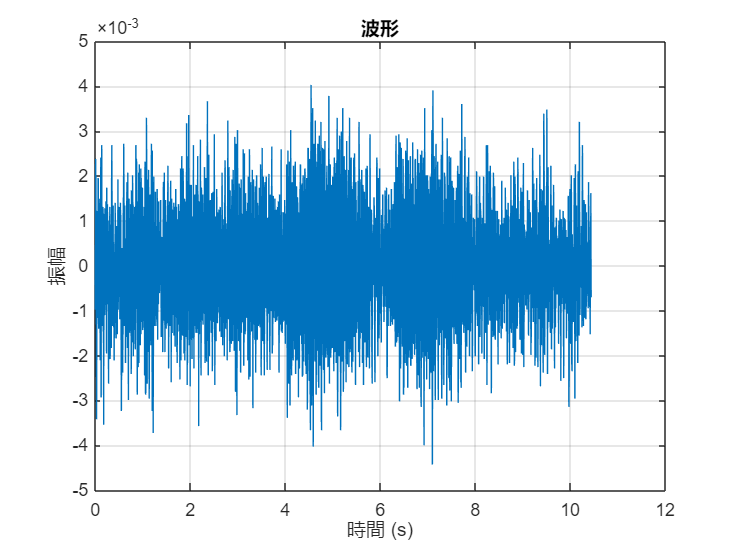


% ============================================================
% 波形表示
% ============================================================
figure(1);
t = (0:length(y)-1) / fs;
plot(t, y);
xlabel('時間 (s)');
ylabel('振幅');
title('波形');
grid on;

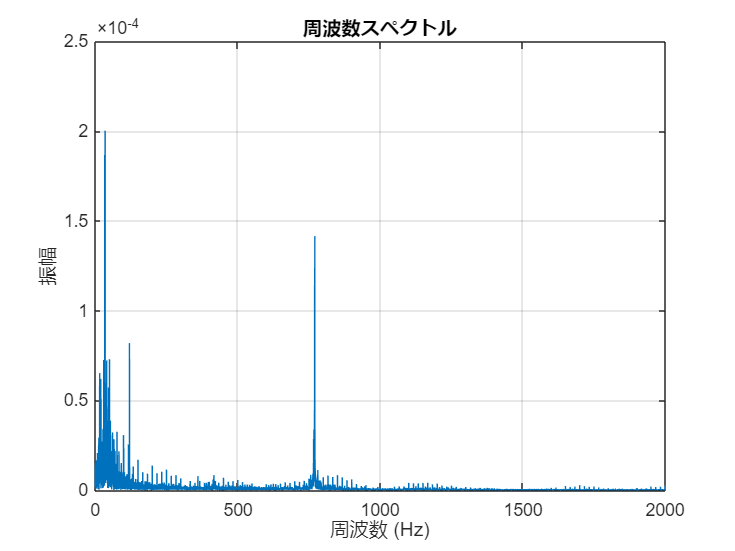


% ============================================================
% FFT（周波数解析）
% ============================================================
N   = length(y);
Y   = fft(y);
f   = (0:N-1) * (fs/N);
amp = abs(Y(1:floor(N/2))) / N;
f   = f(1:floor(N/2));

figure(2);
plot(f, amp);
xlabel('周波数 (Hz)');
ylabel('振幅');
title('周波数スペクトル');
grid on;
xlim([0 fs/2]);


% ============================================================
% Peak Frequency（上位5つ）
% ============================================================
fprintf('\n=== Peak Frequency ===\n');


=== Peak Frequency ===


[sortedAmp, sortedIdx] = sort(amp, 'descend');
fprintf('順位  周波数(Hz)  振幅\n');

順位  周波数(Hz)  振幅


fprintf('----  ----------  --------\n');

----  ----------  --------


for i = 1:5
    fprintf('%3d   %8.1f    %.6f\n', i, f(sortedIdx(i)), sortedAmp(i));
end

  1       34.7    0.000200
  2       33.0    0.000187
  3       34.8    0.000163
  4      770.3    0.000142
  5      770.4    0.000124


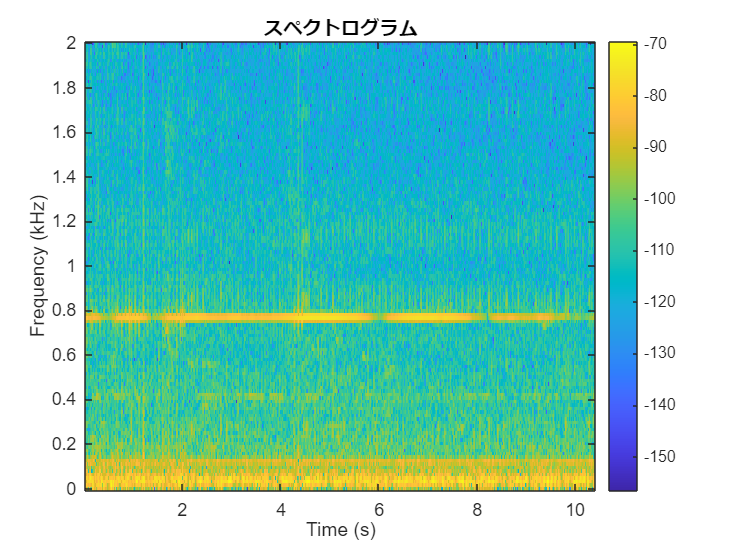


% ============================================================
% スペクトログラム（時間×周波数の2D表示）
% 音がどの時間帯にどの周波数が強いか見える
% ============================================================
figure(3);
spectrogram(y, 256, 200, 256, fs, 'yaxis');
title('スペクトログラム');
colorbar;

% WAV読み込み
[y, fs] = audioread('C:\Users\chika\COMOMO\environment_07.wav');  % ファイル名を実際のものに変更
y = y(:, 1);  % モノラル確認

% ============================================================
% 基本情報
% ============================================================
fprintf('=== 基本情報 ===\n');

=== 基本情報 ===


fprintf('サンプルレート : %d Hz\n', fs);

サンプルレート : 4000 Hz


fprintf('サンプル数     : %d\n', length(y));

サンプル数     : 21120


fprintf('録音時間       : %.2f 秒\n', length(y)/fs);

録音時間       : 5.28 秒


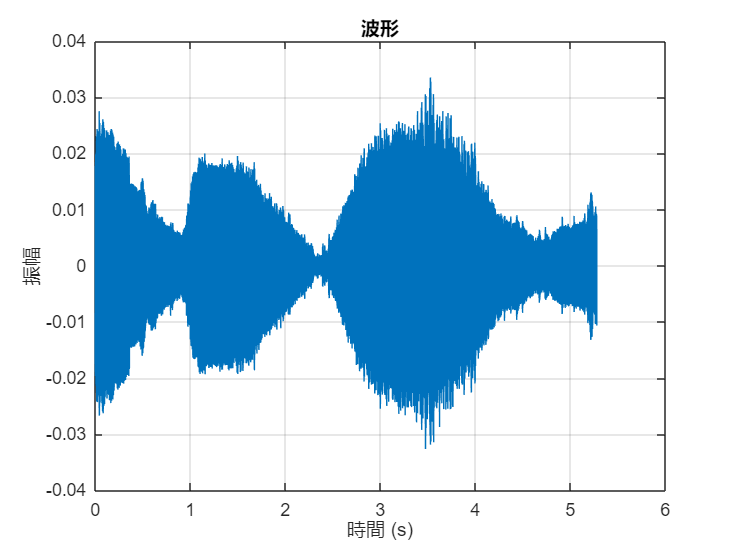


% ============================================================
% 波形表示
% ============================================================
figure(1);
t = (0:length(y)-1) / fs;
plot(t, y);
xlabel('時間 (s)');
ylabel('振幅');
title('波形');
grid on;

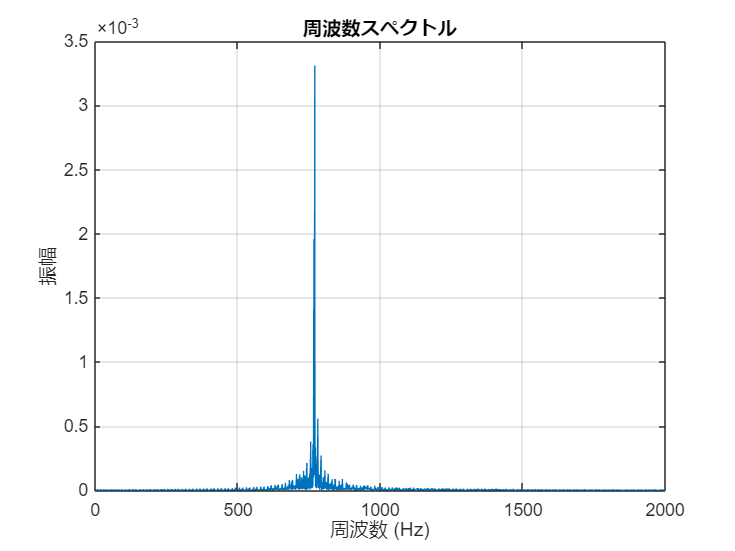


% ============================================================
% FFT（周波数解析）
% ============================================================
N   = length(y);
Y   = fft(y);
f   = (0:N-1) * (fs/N);
amp = abs(Y(1:floor(N/2))) / N;
f   = f(1:floor(N/2));

figure(2);
plot(f, amp);
xlabel('周波数 (Hz)');
ylabel('振幅');
title('周波数スペクトル');
grid on;
xlim([0 fs/2]);


% ============================================================
% Peak Frequency（上位5つ）
% ============================================================
fprintf('\n=== Peak Frequency ===\n');


=== Peak Frequency ===


[sortedAmp, sortedIdx] = sort(amp, 'descend');
fprintf('順位  周波数(Hz)  振幅\n');

順位  周波数(Hz)  振幅


fprintf('----  ----------  --------\n');

----  ----------  --------


for i = 1:5
    fprintf('%3d   %8.1f    %.6f\n', i, f(sortedIdx(i)), sortedAmp(i));
end

  1      770.3    0.003312
  2      769.9    0.002768
  3      770.1    0.002408
  4      770.5    0.002057
  5      767.4    0.001958


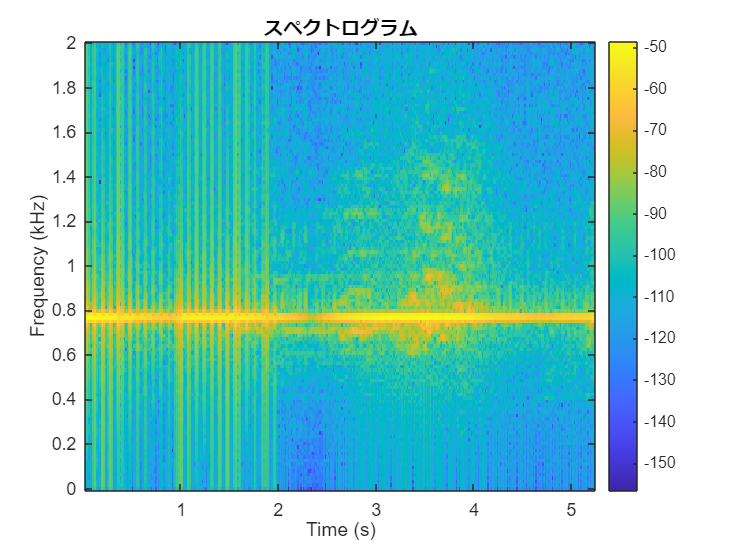


% ============================================================
% スペクトログラム（時間×周波数の2D表示）
% 音がどの時間帯にどの周波数が強いか見える
% ============================================================
figure(3);
spectrogram(y, 256, 200, 256, fs, 'yaxis');
title('スペクトログラム');
colorbar;

% WAV読み込み
[y, fs] = audioread('C:\Users\chika\COMOMO\environment_08.wav');  % ファイル名を実際のものに変更
y = y(:, 1);  % モノラル確認

% ============================================================
% 基本情報
% ============================================================
fprintf('=== 基本情報 ===\n');

=== 基本情報 ===


fprintf('サンプルレート : %d Hz\n', fs);

サンプルレート : 4000 Hz


fprintf('サンプル数     : %d\n', length(y));

サンプル数     : 40640


fprintf('録音時間       : %.2f 秒\n', length(y)/fs);

録音時間       : 10.16 秒


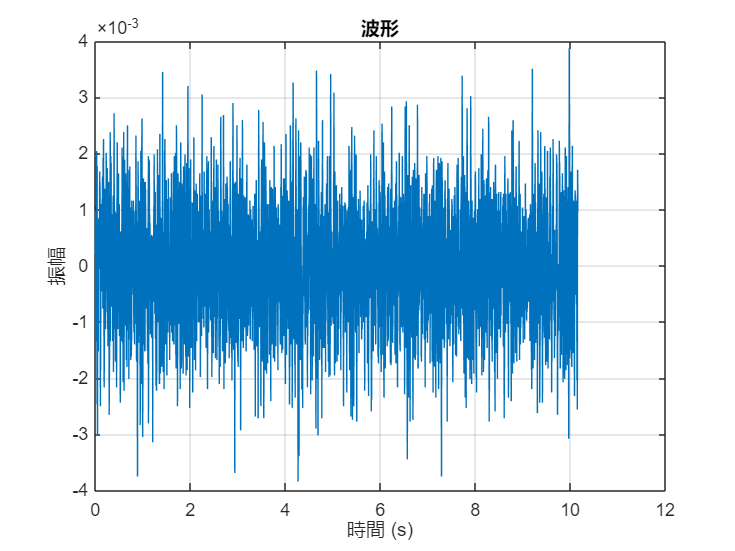


% ============================================================
% 波形表示
% ============================================================
figure(1);
t = (0:length(y)-1) / fs;
plot(t, y);
xlabel('時間 (s)');
ylabel('振幅');
title('波形');
grid on;

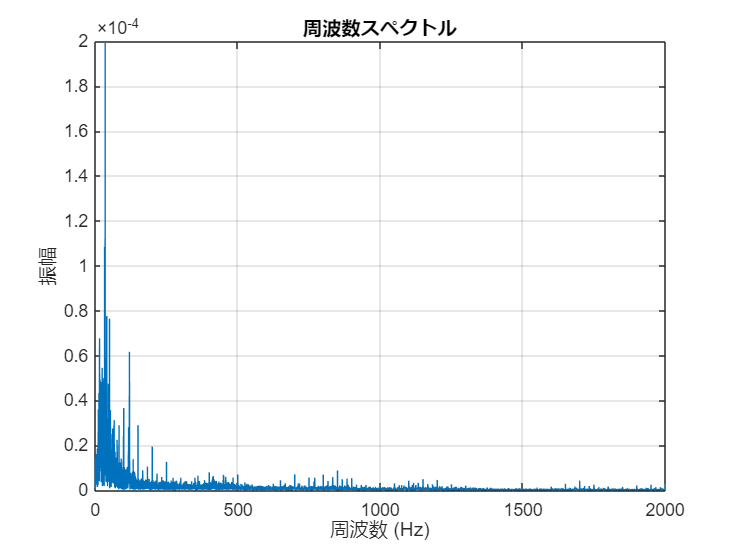


% ============================================================
% FFT（周波数解析）
% ============================================================
N   = length(y);
Y   = fft(y);
f   = (0:N-1) * (fs/N);
amp = abs(Y(1:floor(N/2))) / N;
f   = f(1:floor(N/2));

figure(2);
plot(f, amp);
xlabel('周波数 (Hz)');
ylabel('振幅');
title('周波数スペクトル');
grid on;
xlim([0 fs/2]);


% ============================================================
% Peak Frequency（上位5つ）
% ============================================================
fprintf('\n=== Peak Frequency ===\n');


=== Peak Frequency ===


[sortedAmp, sortedIdx] = sort(amp, 'descend');
fprintf('順位  周波数(Hz)  振幅\n');

順位  周波数(Hz)  振幅


fprintf('----  ----------  --------\n');

----  ----------  --------


for i = 1:5
    fprintf('%3d   %8.1f    %.6f\n', i, f(sortedIdx(i)), sortedAmp(i));
end

  1       34.7    0.000200
  2       34.4    0.000112
  3       32.9    0.000108
  4       33.2    0.000095
  5       33.0    0.000087


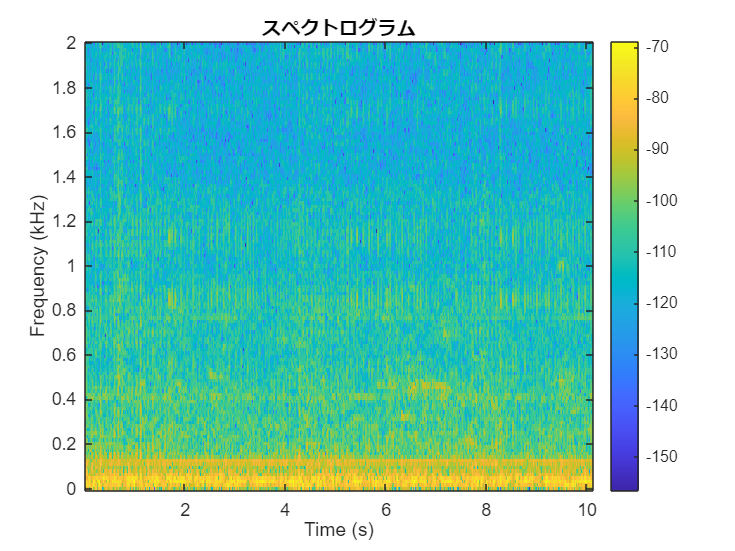


% ============================================================
% スペクトログラム（時間×周波数の2D表示）
% 音がどの時間帯にどの周波数が強いか見える
% ============================================================
figure(3);
spectrogram(y, 256, 200, 256, fs, 'yaxis');
title('スペクトログラム');
colorbar;

% WAV読み込み
[y, fs] = audioread('C:\Users\chika\COMOMO\1to501hz_08.wav');  % ファイル名を実際のものに変更
y = y(:, 1);  % モノラル確認

% ============================================================
% 基本情報
% ============================================================
fprintf('=== 基本情報 ===\n');

=== 基本情報 ===


fprintf('サンプルレート : %d Hz\n', fs);

サンプルレート : 4000 Hz


fprintf('サンプル数     : %d\n', length(y));

サンプル数     : 115200


fprintf('録音時間       : %.2f 秒\n', length(y)/fs);

録音時間       : 28.80 秒


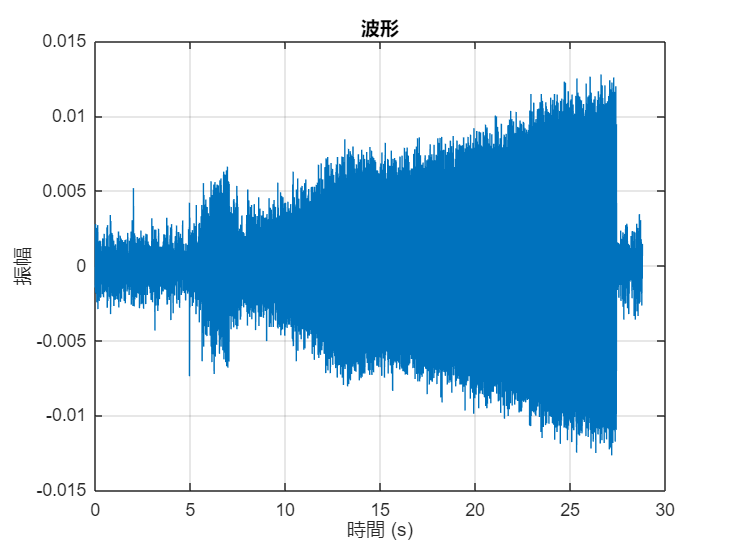


% ============================================================
% 波形表示
% ============================================================
figure(1);
t = (0:length(y)-1) / fs;
plot(t, y);
xlabel('時間 (s)');
ylabel('振幅');
title('波形');
grid on;

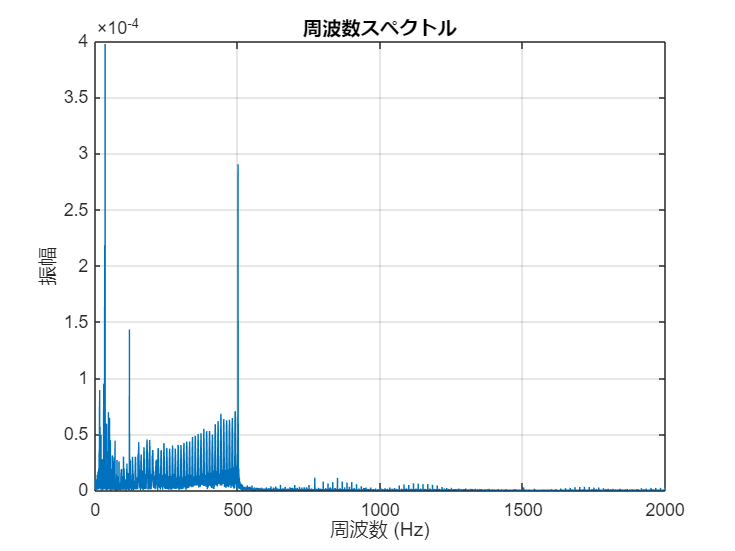


% ============================================================
% FFT（周波数解析）
% ============================================================
N   = length(y);
Y   = fft(y);
f   = (0:N-1) * (fs/N);
amp = abs(Y(1:floor(N/2))) / N;
f   = f(1:floor(N/2));

figure(2);
plot(f, amp);
xlabel('周波数 (Hz)');
ylabel('振幅');
title('周波数スペクトル');
grid on;
xlim([0 fs/2]);


% ============================================================
% Peak Frequency（上位5つ）
% ============================================================
fprintf('\n=== Peak Frequency ===\n');


=== Peak Frequency ===


[sortedAmp, sortedIdx] = sort(amp, 'descend');
fprintf('順位  周波数(Hz)  振幅\n');

順位  周波数(Hz)  振幅


fprintf('----  ----------  --------\n');

----  ----------  --------


for i = 1:5
    fprintf('%3d   %8.1f    %.6f\n', i, f(sortedIdx(i)), sortedAmp(i));
end

  1       34.7    0.000398
  2      501.0    0.000290
  3      501.0    0.000290
  4      501.0    0.000287
  5      500.9    0.000287


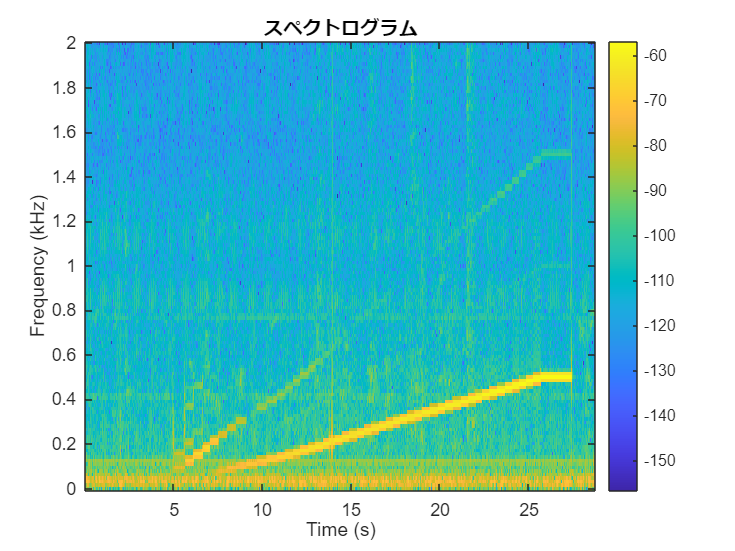


% ============================================================
% スペクトログラム（時間×周波数の2D表示）
% 音がどの時間帯にどの周波数が強いか見える
% ============================================================
figure(3);
spectrogram(y, 256, 200, 256, fs, 'yaxis');
title('スペクトログラム');
colorbar;

% WAV読み込み
[y, fs] = audioread('C:\Users\chika\COMOMO\501to2101hz_08.wav');  % ファイル名を実際のものに変更
y = y(:, 1);  % モノラル確認

% ============================================================
% 基本情報
% ============================================================
fprintf('=== 基本情報 ===\n');

=== 基本情報 ===


fprintf('サンプルレート : %d Hz\n', fs);

サンプルレート : 4000 Hz


fprintf('サンプル数     : %d\n', length(y));

サンプル数     : 195520


fprintf('録音時間       : %.2f 秒\n', length(y)/fs);

録音時間       : 48.88 秒


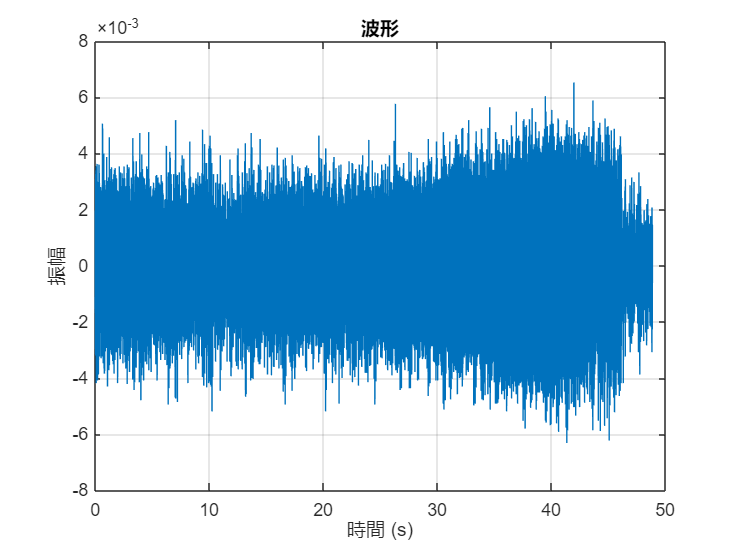


% ============================================================
% 波形表示
% ============================================================
figure(1);
t = (0:length(y)-1) / fs;
plot(t, y);
xlabel('時間 (s)');
ylabel('振幅');
title('波形');
grid on;

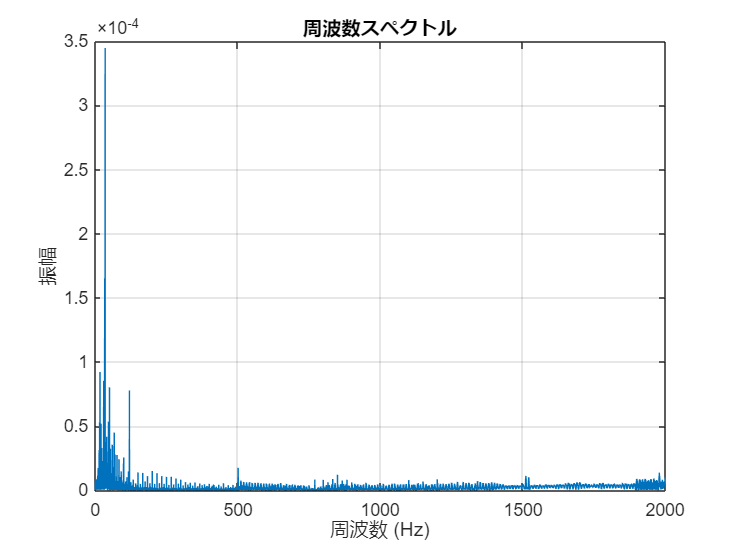


% ============================================================
% FFT（周波数解析）
% ============================================================
N   = length(y);
Y   = fft(y);
f   = (0:N-1) * (fs/N);
amp = abs(Y(1:floor(N/2))) / N;
f   = f(1:floor(N/2));

figure(2);
plot(f, amp);
xlabel('周波数 (Hz)');
ylabel('振幅');
title('周波数スペクトル');
grid on;
xlim([0 fs/2]);


% ============================================================
% Peak Frequency（上位5つ）
% ============================================================
fprintf('\n=== Peak Frequency ===\n');


=== Peak Frequency ===


[sortedAmp, sortedIdx] = sort(amp, 'descend');
fprintf('順位  周波数(Hz)  振幅\n');

順位  周波数(Hz)  振幅


fprintf('----  ----------  --------\n');

----  ----------  --------


for i = 1:5
    fprintf('%3d   %8.1f    %.6f\n', i, f(sortedIdx(i)), sortedAmp(i));
end

  1       34.7    0.000345
  2       33.0    0.000165
  3       33.1    0.000099
  4       16.7    0.000092
  5       33.0    0.000092


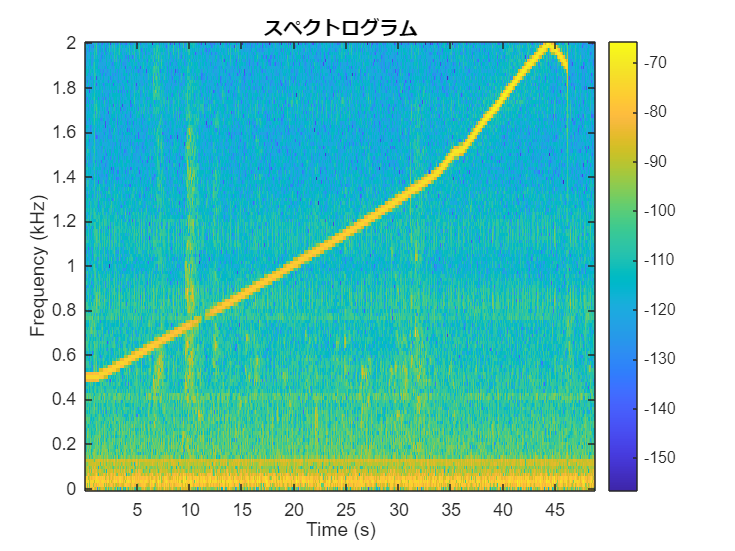


% ============================================================
% スペクトログラム（時間×周波数の2D表示）
% 音がどの時間帯にどの周波数が強いか見える
% ============================================================
figure(3);
spectrogram(y, 256, 200, 256, fs, 'yaxis');
title('スペクトログラム');
colorbar;